# EJERCICIO 4 (Opción B)

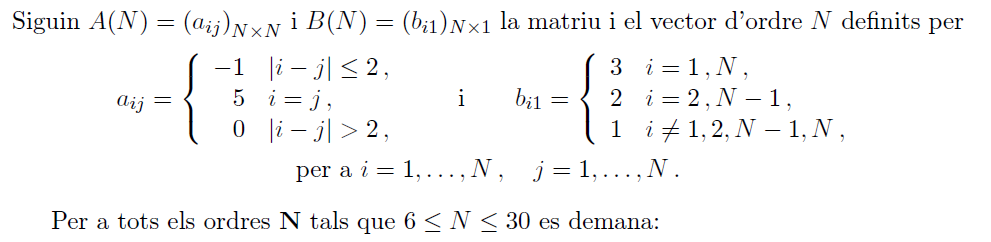

### CALCULOS

clear
format shortG

RESULT = [];

for N = 6:30
    % Crear A
    A = zeros(N);
    for j = 1:N
        for i = 1:N
            A(i,j) = -(abs(i - j) <= 2) + (i == j)*6;
        end
    end
    
    % Crear B
    b = ones(N,1); b(1) = 3; b(2) = 2; b(N-1) = 2; b(N) = 3; 
    
    S.N = N;
    S.A = A;
    S.b = b;
    
    S.determinante = det(A);
    S.num_condicion = cond(A);
    S.simetrica = issymmetric(A);
    
    % Metodo de eliminacion gaussiana
    S.eliminacion_gaussiana_sol = metodoGaussiano(A,b);
    
    % Metodo de factorizacion QR
    S.QR_sol = metodoQR(A, b);
    
    % Matrices comunes necesarias (GS/J)
    D = diag(diag(A));
    d = diag(1 ./diag(A));
    L = tril(A,-1);
    U = triu(A,1);
        
    % Metodo de Gauss-Seidel
    [solGS, itGS, es_convergenteGS ,radi_espGS] = metodoGaussSeidel(b,D,L,U,eps);
    
    S.gauss_seidel_sol = solGS;
    S.gauss_seidel_residuo = norm(b - A*solGS, 'Inf');
    S.gauss_seidel_it = itGS;
    S.gauss_seidel_conv = es_convergenteGS;
    S.gauss_seidel_radi_esp = radi_espGS;
    
    % Metodo de Jacobi
    [solJ, itJ, es_convergenteJ, radi_espJ] = metodoJacobi(A,b,D,d,eps);
    S.jacobi_sol = solJ;
    S.jacobi_residuo = norm(b - A*solGS, 'Inf');
    S.jacobi_it = itJ;
    S.jacobi_radi_esp = radi_espJ;
    S.jacobi_conv = es_convergenteJ;
    
    RESULT = [RESULT S];
    
end

% Para posteriores comparaciones
epsilon = [eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps eps];

### EXTRACCION DE RESULTADOS

#### 

for k = 1:25
    determinantes(k) = RESULT(k).determinante;
    condiciones(k) = RESULT(k).num_condicion;
    simetricas(k) = RESULT(k).simetrica;
end

R1 = [determinantes' condiciones' simetricas'];
T1 = array2table([[6:30]' R1], "VariableNames", {'N', 'Determinante', 'NumeroCondicion', 'Simetrica'})

T1 = 25×4 table
    N     Determinante    NumeroCondicion    Simetrica
    __    ____________    _______________    _________

     6           9313         3.7413             1    
     7          40920         4.1779             1    
     8     1.7971e+05         4.5483             1    
     9      7.891e+05         4.8915             1    
    10     3.4645e+06         5.1419             1    
    11     1.5211e+07         5.4048             1    
    12     6.6779e+07         5.5974             1    
    13     2.9318e+08         5.7765             1    
    14     1.2871e+09         5.9272             1    
    15     5.6509e+09         6.0506             1    
    16     2.4809e+10         6.1701             1    
    17     1.0892e+11         6.2604             1    
    18     4.7817e+11         6.3527             1    
    19     2.0993e+12 

for k = 1:25    
    diffG(k) = norm(RESULT(k).eliminacion_gaussiana_sol - 1);
end

array2table(diffG', "VariableNames", {'Delta'})

ans = 25×1 table
      Delta   
    __________

    2.2204e-16
    3.1402e-16
    3.8459e-16
    3.8459e-16
    3.8459e-16
    4.4409e-16
    6.2804e-16
    7.0217e-16
    7.3644e-16
    7.6919e-16
    7.6919e-16
    7.6919e-16
    8.3081e-16
    1.3688e-15
    8.0059e-16
    8.0059e-16


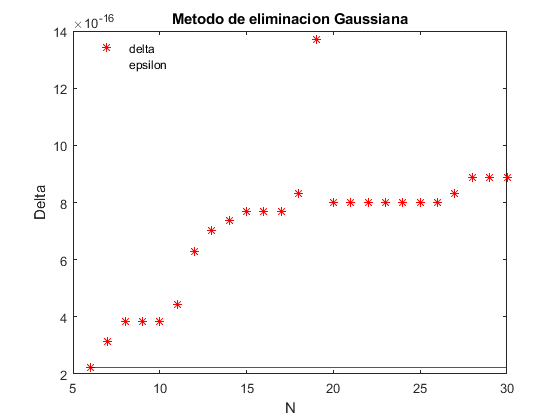

plot([6:30], diffG,'*r',[6:30], epsilon, '-b');
legend('delta', 'epsilon','Location', "best"); xlabel('N'); ylabel("Delta");
title('Metodo de eliminacion Gaussiana')

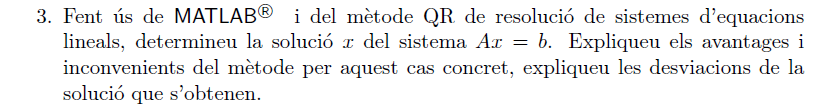

for k = 1:25    
    diffQR(k) = norm(RESULT(k).QR_sol - 1);
end

array2table(diffQR', "VariableNames", {'Delta'})

ans = 25×1 table
      Delta   
    __________

    5.0877e-16
    1.0053e-15
    7.1089e-16
    8.9509e-16
    7.0217e-16
    1.0053e-15
    9.4857e-16
    9.4857e-16
      1.72e-15
    1.9101e-15
    1.5344e-15
     1.923e-15
    2.2807e-15
    2.2888e-15
    1.9069e-15
    2.0199e-15


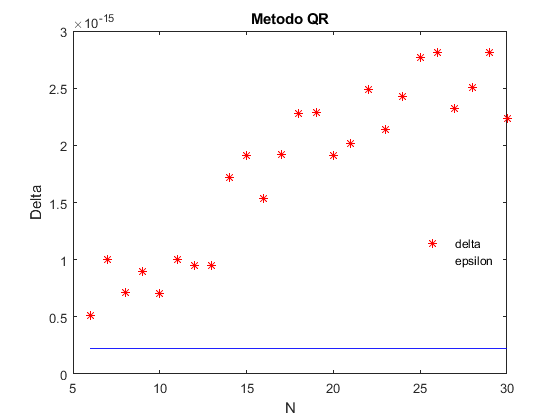

plot([6:30], diffQR,'*r',[6:30], epsilon, '-b');
legend('delta', 'epsilon','Location', "best"); xlabel('N'); ylabel("Delta");
title('Metodo QR')

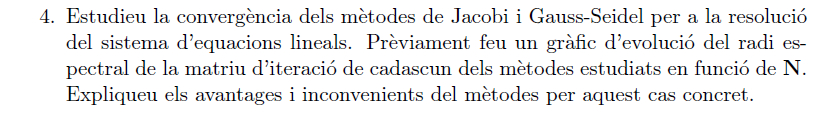


for k = 1:25    
    convGS(k) = RESULT(k).gauss_seidel_conv;
    convJ(k) = RESULT(k).jacobi_conv;
    radioGS(k) = RESULT(k).gauss_seidel_radi_esp;
    radioJ(k)= RESULT(k).jacobi_radi_esp;
end

% Convergencia a priori
R4 = [min(convGS)' min(convJ)'];
array2table(R4, "VariableNames", {'convGS','convJ'})

ans = 1×2 table
    convGS    convJ
    ______    _____

    true      true 


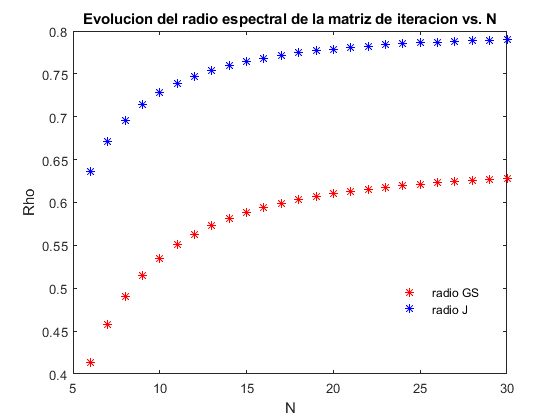

% Grafica del radio espectral
plot([6:30], radioGS,'*r', [6:30], radioJ,'*b');
legend('radio GS','radio J','Location', "best"); xlabel('N'); ylabel("Rho");
title('Evolucion del radio espectral de la matriz de iteracion vs. N')

   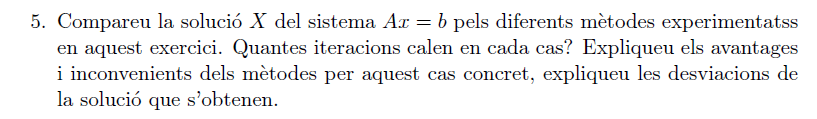

for k = 6-5:30-5
    diffGS(k) = norm(RESULT(k).gauss_seidel_sol - 1);
    diffJ(k) = norm(RESULT(k).jacobi_sol - 1);
    itG(k) = RESULT(k).gauss_seidel_it;
    itJ(k) = RESULT(k).jacobi_it;
end
itT = [itG' itJ'];
solT = [ diffGS' diffJ'];

% Deltas
array2table(solT, "VariableNames", {'deltaGS', 'deltaJ'})

ans = 25×2 table
     deltaGS        deltaJ  
    __________    __________

    2.2204e-16    3.5108e-16
    3.8459e-16    4.1541e-16
    3.1402e-16    1.0175e-15
    3.5108e-16    5.2074e-16
    4.4409e-16    5.2074e-16
    3.5108e-16     5.661e-16
    4.9651e-16    6.0809e-16
    6.6613e-16    1.0991e-15
    7.0217e-16    6.3777e-16
    5.8747e-16    6.7532e-16
    7.3644e-16     1.143e-15
    9.4206e-16    1.2263e-15
    1.1102e-15    1.3042e-15
    1.1322e-15    1.2658e-15
    1.3323e-15    1.3955e-15
    8.7419e-16    1.2804e-15


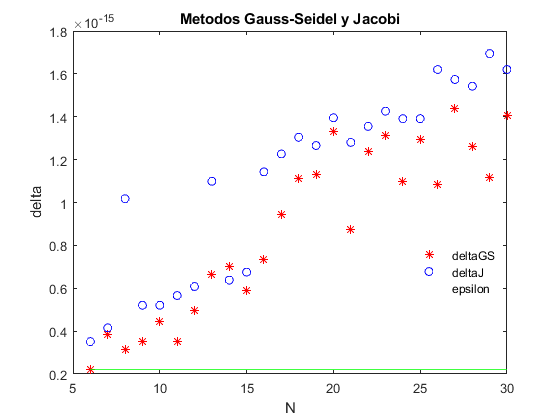

plot([6:30], solT(:,1) ,'*r', [6:30], solT(:,2),'ob', [6:30], epsilon, '-g');
legend('deltaGS', 'deltaJ', 'epsilon','Location', "best"); xlabel('N'); ylabel("delta");
title('Metodos Gauss-Seidel y Jacobi')

% Iteraciones
array2table(itT, "VariableNames", {'itGS', 'itJ'})

ans = 25×2 table
    itGS    itJ
    ____    ___

     42      79
     48      89
     52      97
     55     106
     59     112
     61     118
     64     122
     66     125
     69     130
     69     133
     71     134
     72     136
     73     138
     74     140
     75     141
     75     143


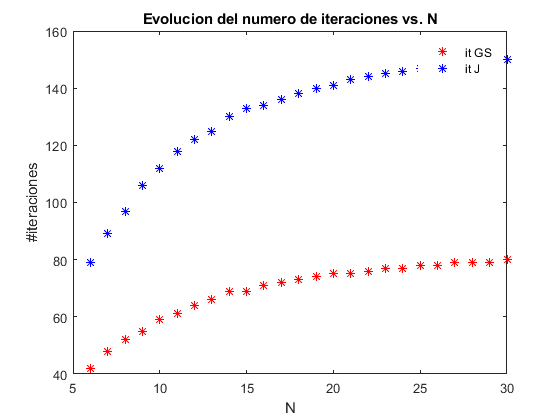

plot([6:30], itT(:,1) ,'*r', [6:30], itT(:,2),'*b');
legend('it GS','it J'); xlabel('N'); ylabel("#iteraciones");
title('Evolucion del numero de iteraciones vs. N')

#### FUNCIONES CON LOS DIFERENTES METODOS DE RESOLUCION DE SISTEMAS

function x = metodoQR(A, b)
    [q, r] = qr(A);
    x = backsubs(r,(q'*b));
end

function x = metodoGaussiano(A,b)
    [L,U,P] = lu(A);     % Factorizacion en 2 triagulares
    y = L\(P*b);         % 1) Ly = Pb
    x = U\y;             % 2) Ux = y
end

function [x, it, es_convergente, rhoGS] = metodoGaussSeidel(b,D,L,U,tol)
    C = inv(L+D);
    Bgs = -C*U;
    cgs = C*b;
    rhoGS = max(abs(eig(Bgs)));
    if (rhoGS >= 1) 
        x = []; it = 0;
        es_convergente = false;
    else
        es_convergente = true;
        B=Bgs; c=cgs; it = 0; error_aprox = 1;
        x=zeros(size(b));
        
        while error_aprox > tol
            it = it + 1;
            next_x = B*x+c;
            error_aprox = norm(next_x - x,'inf');
            
            x = next_x;
        end
    end
end

function [x, it, es_convergente, rhoJ] = metodoJacobi(A,b,D,d,tol)

    Bj = -d*(A-D);
    cj = d*b;
    rhoJ = max(abs(eig(Bj)));
    if (rhoJ >= 1)
        x = []; it = 0;
        es_convergente = false;
    else
        es_convergente = true;
        B = Bj; c = cj; it = 0; error_aprox = 1;
        x = zeros(size(b));
        
        while error_aprox > tol
            next_x = B*x+c;
            error_aprox = norm(next_x - x,'inf');
            x = next_x;
            it = it + 1;
        end
    end
end